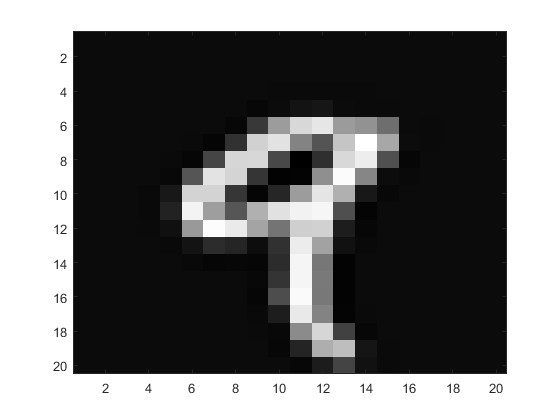

clear; clc; close all;

load digit_data;

for x = 1:500:4501
    figure;
    imagesc(images(:,:,x));
    colormap(gray(256));
end

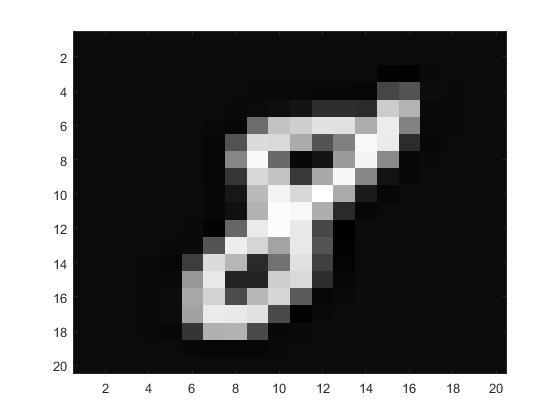

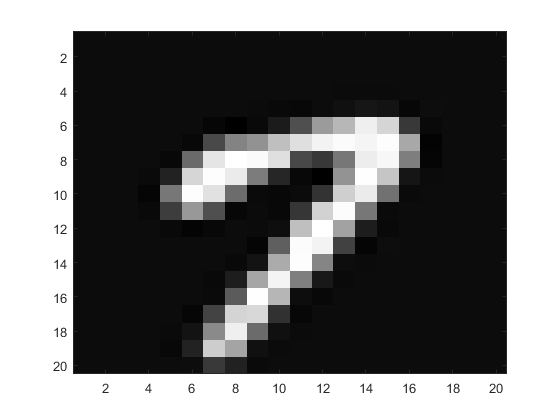

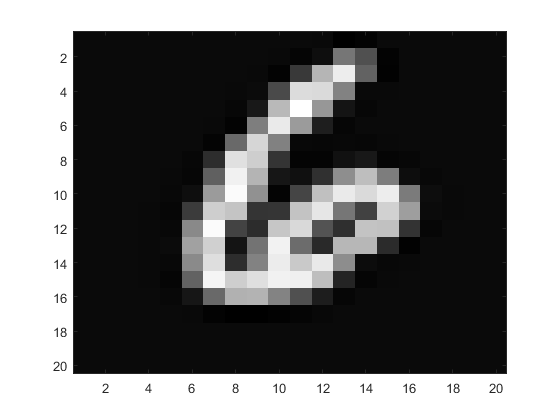

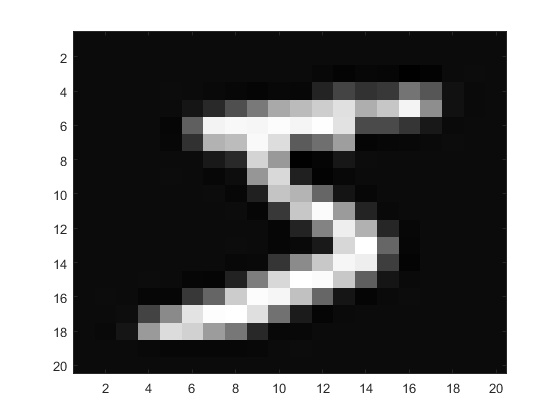

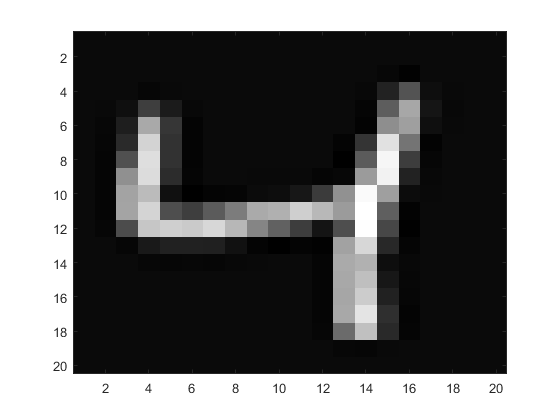

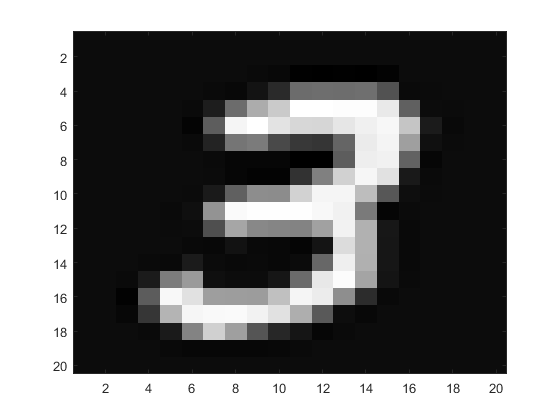

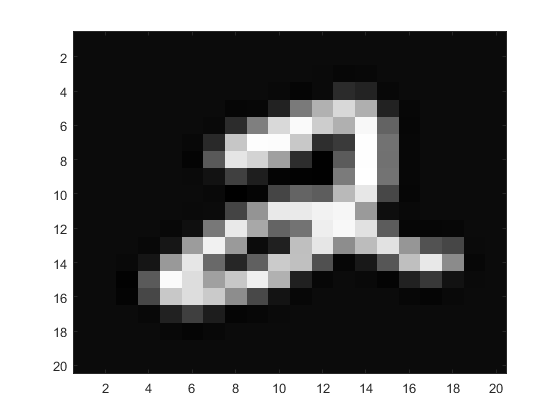

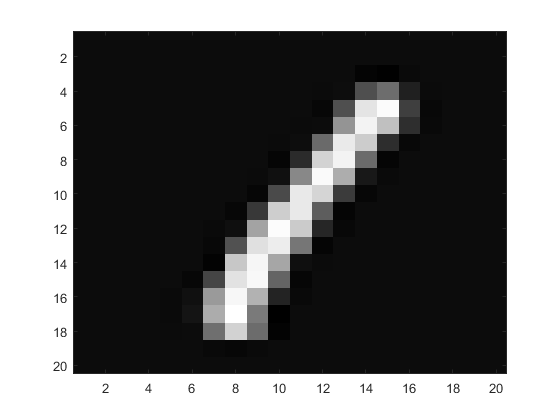


test_indices = (1:60:5000);
train_init = (1:5000);
train_indices = setdiff(train_init, test_indices);

test_images = images(:,:, test_indices);
train_images = images(:,:,train_indices);

train_labels = labels(train_indices);
test_labels = labels(test_indices);

for y=1:84
    for z=1:4916
        distance(z)=sqrt(sum(sum((train_images(:,:,z)-test_images(:,:, y)).^2)));
    end

[min_dist, min_index(y)]=min(distance);
predict(y)=train_labels(min_index(y));
end

right = 0;
wrong = 0;

for c=1:84
    subplot(1 ,2, 1);
    imagesc(test_images(:,:,c));
    colormap(gray(256)); 
    title(sprintf("Test Image, Actual Label: %d", test_labels(c))); 
    subplot(1, 2, 2); 
    imagesc(train_images(:, :, min_index(c)));
    colormap(gray(256)); 
    title(sprintf("Closest Match, Predicted Label: %d", predict(c))); 
    pause(0.3);
    
    if test_labels(c) == predict(c)
        right = right + 1;
    else
        wrong = wrong + 1;
    end
end

disp(right)

    78



disp(wrong)

     6

